# Gruppe1 PBL - Main

Load the measured data into the workspace.

After this part any of the modules can be executed savely since it resets the input.

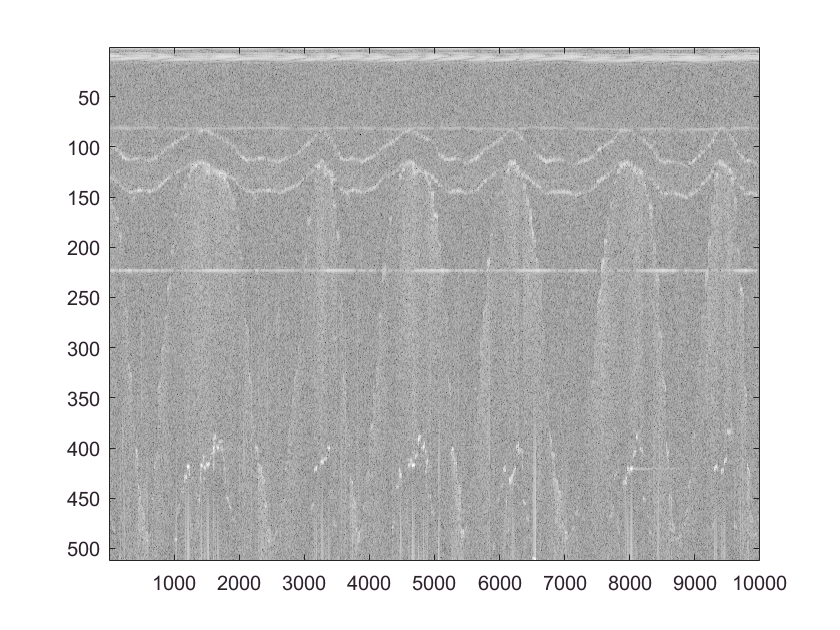

close all;
clear all;
% the filename is put into its own variable so we can display and save it in the submodules along with the parameters
% to remember "working configurations"
% filename = "09052017034909__ascan_3.bin";
filename = '09052017034420__ascan_2.bin';
filehandle = fopen(filename);
mscan = fread(filehandle,'float32');

bildhoehe = 512; % vorgegeben von Tutor

C = reshape(mscan,bildhoehe,[]);
clear mscan; % free up memory
% Scaling of values to [0,1] for compatibility with imshow / imagesc
CMAX=max(C(:));
C = C /CMAX ;

% Auswahl des anzuzeigenden Bereichs
C = C(:,1:10000);
original = C;

colormap gray;
imagesc(C);

Convert the MScan into BScans using one of our methods:

09052017034420__ascan_2.bin


A =     80
    80
    80
    80
    80
    80
    80
    80


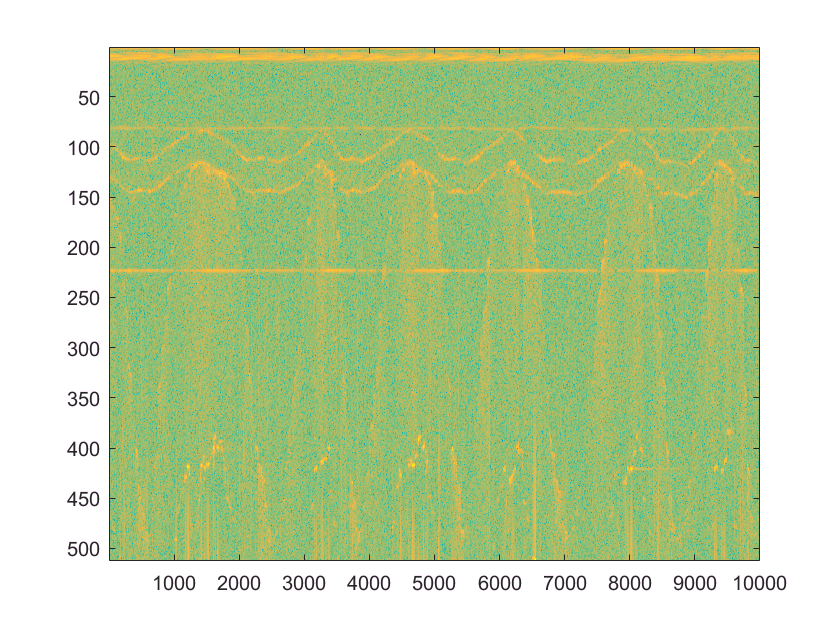

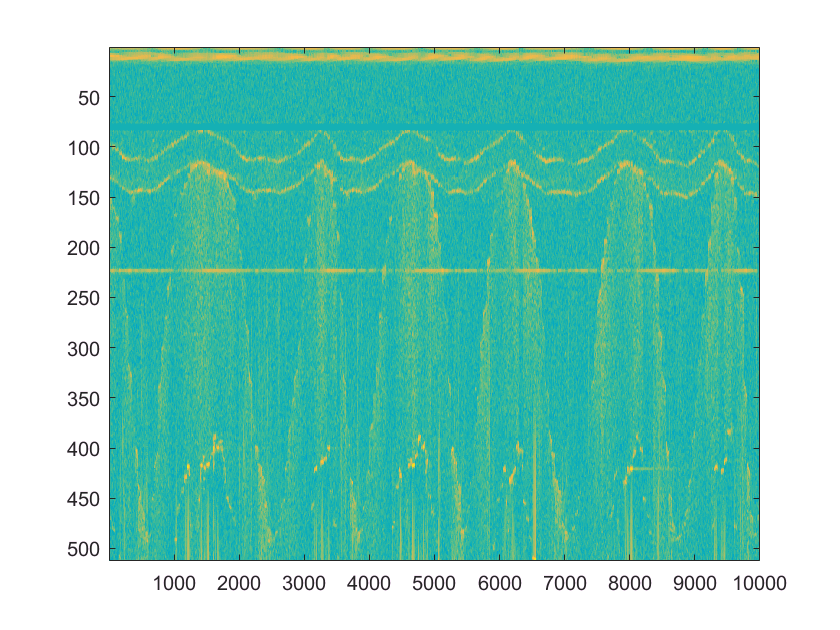

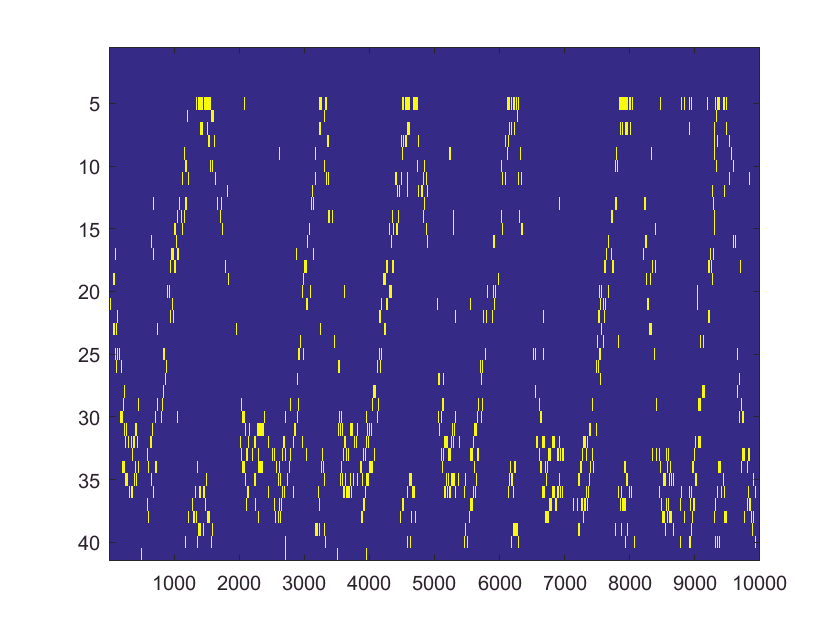

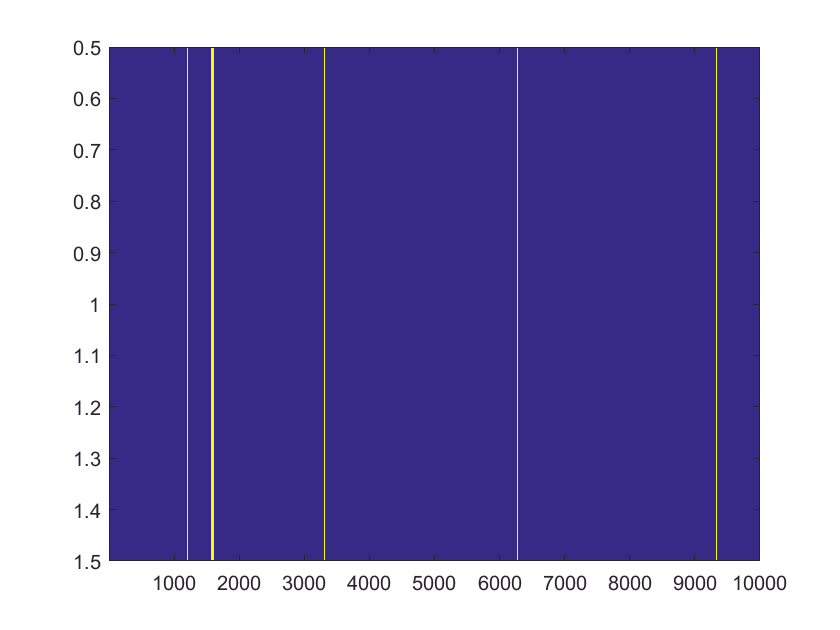

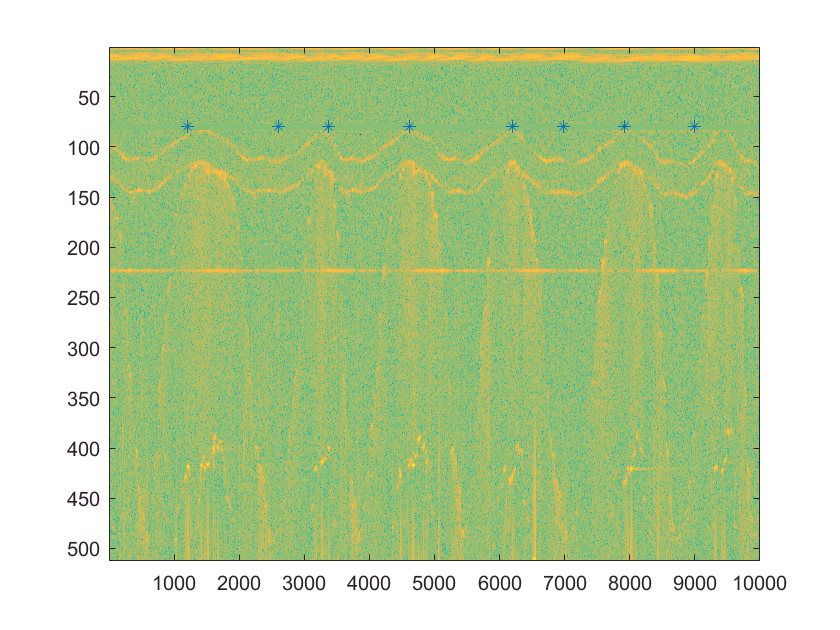

%PBL_MScan2Bscan_Gapfinder();
% Alexandra's method
MtoBscan();

% Alex's method

Filter artefacts

PBL_Filter_Artefacts();

Error: File: PBL_Filter_Artefacts.mlx Line: 35 Column: 14
Creating a string using double quotes is not supported.  Use the string function.

Interpolation and coordinate transformation

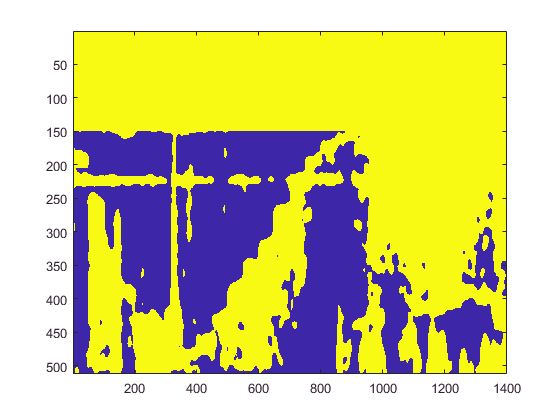

FinishedBScan = Artefact1(:,3500:4900); %todo, artefact 2 algo left out here
FinishedBScan(1:150,:) = 1;
figure; %attempt to correct the image display
imagesc(FinishedBScan);

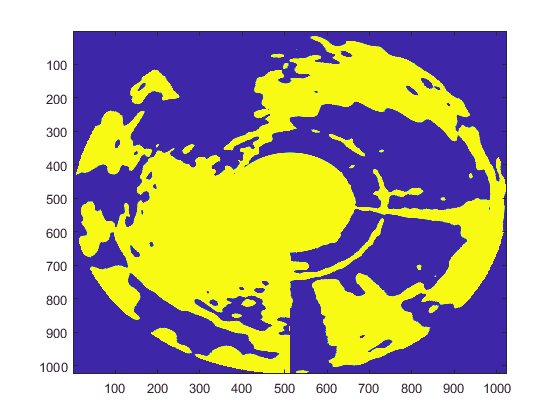

figure;
N = 512*2;
M = N;
imR = PolarToIm (FinishedBScan, 0, 1, M, N);
imagesc(imR);